**6 Comparison Bode Plots of Derived Simple DC-DC Buck Converter (Simple LC Filter) and Derived Real DC-DC Buck Converter (Real LC Filter)**

clc; 
clear all; 
close all;

%Identify Transfer Function Variable
s = tf('s');

% Buck Converter Values
R = 10;         % Load resistance (Ohm)
L = 350e-6;     % Inductor value (H)
C = 100e-6;     % Capacitor value (F)
RL = 0.050;     % Inductor resistance (Ohm)
RC = 0.025;     % Capacitor resistance (Ohm)
Vin = 12;       % Input Voltage value (V)

% Transfer Function for Simple Buck Converter
SIMPBUCKTF = Vin*(R/ (R+s*L+(s^2)*R*L*C))

SIMPBUCKTF =
 
              120
  ----------------------------
  3.5e-07 s^2 + 0.00035 s + 10
 
Continuous-time transfer function.
Model Properties



% Transfer Function for Real Buck Converter
REALBUCKTOP = 1+(C*RC)*s;
REALBUCKBOTTOM = 1+(RL/R)+(L/R+RC*C+RL*C+(RL*RC*C)/R)*s+((R+RC)/R)*L*C*(s^2);
REALBUCKTF = Vin*(REALBUCKTOP/REALBUCKBOTTOM)

REALBUCKTF =
 
             3e-05 s + 12
  -----------------------------------
  3.509e-08 s^2 + 4.251e-05 s + 1.005
 
Continuous-time transfer function.
Model Properties


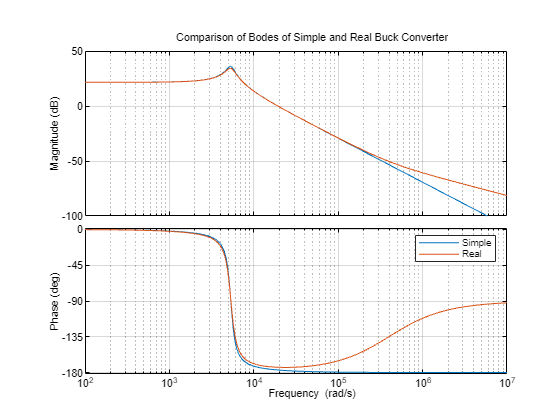


% Comparison Bode Plot Displayed
figure()
options = bodeoptions;
options.FreqUnits = 'rad/s';
bode(SIMPBUCKTF, options); hold on;
bode(REALBUCKTF,options);
grid on
legend('Simple', 'Real')
title('Comparison of Bodes of Simple and Real Buck Converter')